# Loading The Diabetes Data Set

clear
clc
load pimadiabetes.mat

## Starting PCA method

Mean = mean(Features)  ;                % get mean value of each column
NewFeatures = (Features - Mean) ./ std(Features)   ; % Center all values to mean and set standard deviation to 1
cov = (NewFeatures'*NewFeatures) ./ (size(NewFeatures,1)-1);
[U,Ei,Coeff] = svd(cov);   % Use singluar Value Decomposition to obtain Eigen vector (E) ,principal component matrix(coeff)
S = NewFeatures*Coeff;               %Obtain the score of the matrix
[A B C D E] = pca(cov); % E shows the variance explained by each of the components
E

E =    48.3102
   16.7263
   12.9755
    9.3712
    7.2605
    2.8096
    2.5468


## Extracting the first the 3 principal components


S = [S , diabetesOutput];           % Adding the column diabetesOutput which has 0 and 1 indicating diabetic or not
SNDiabetic = [];
SDiabetic = [] ;
for i = 1:size(diabetesOutput,1)
    if(S(i,9) ==0 )
        SNDiabetic = [SNDiabetic ; S(i,:)];           % If 0 add it to the not-diabetic matrix
    else
        SDiabetic = [SDiabetic ; S(i,:)];
    end
end
% we extract the first 3 components of the score matrix to make a 3D plot
SNDiabetic = SNDiabetic(:,[1,2,3]); 
SDiabetic = SDiabetic(:,[1,2,3]);

## **Plotting the Principle components onto a 3D Graph**

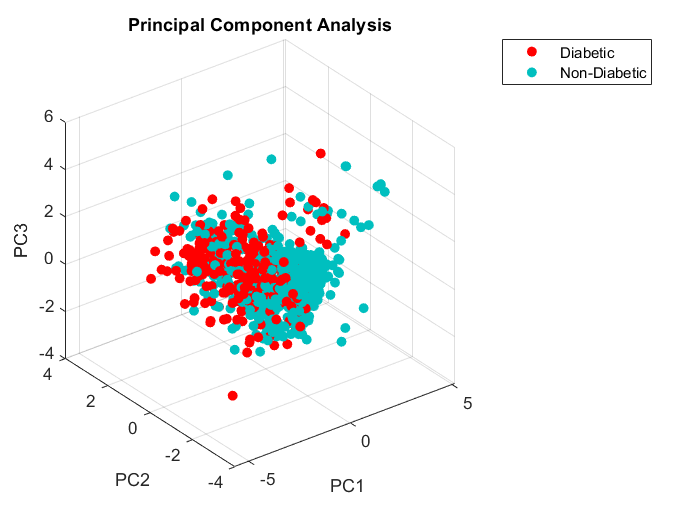


scatter3(SDiabetic(:,1),SDiabetic(:,2),SDiabetic(:,3),'filled' , 'MarkerFaceColor',[1 0 .0])    % plot Diabetic patients with a red filled dot
hold on
scatter3(SNDiabetic(:,1),SNDiabetic(:,2),SNDiabetic(:,3),'filled' ,'MarkerFaceColor',[0 .75 .75]) % plot non-Diabetic patients with a blue filled dot
% Given Below are steps to make the plot labelled
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
title("Principal Component Analysis")

legend('Diabetic' , 'Non-Diabetic')
% ^ end of the labelling steps ^
hold off

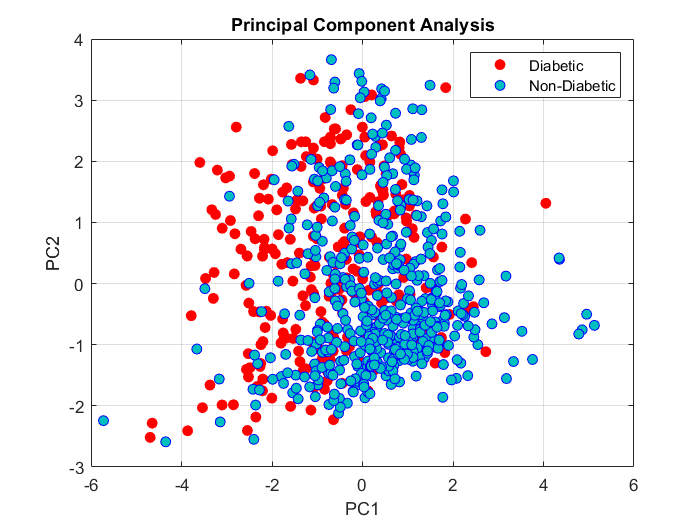

% Given below are to plot a 2D plot of the same above 3D plot but only using 2 Principal components
plot(SDiabetic(:,1),SDiabetic(:,2),'ro','MarkerFaceColor',[1 0 .0])
hold on
plot(SNDiabetic(:,1),SNDiabetic(:,2),'bo','MarkerFaceColor',[0 .75 .75])
xlabel('PC1')
ylabel('PC2')
title("Principal Component Analysis")
legend('Diabetic' , 'Non-Diabetic')

grid on